clc
clear all

% Get RIR from the sine sweep measurements

[sine_sweep,fs] = audioread('python_sweep_files/inverse.wav');
sine_sweep = sine_sweep(97:end); % Had to remove the first element because it was 0 and the deconv function complained
length(sine_sweep)

ans = 479904

number_of_discrete_positions = 12;
number_of_speakers = 2;

number_of_mics = ['A','B','C','D','E','F'];

speakers_all_discrete_positions = cell(number_of_discrete_positions,number_of_speakers);

for i=1:number_of_discrete_positions
    for j=1:length(number_of_mics)
        %disp(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(3+i) '.wav'])
        %disp('-----')
        if i+3 >= 10
            [audioData, fs] = audioread(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(3+i) '.wav']);
        else
            [audioData, fs] = audioread(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_00' num2str(3+i) '.wav']);
        end
        truncatedAudioData = audioData(1:length(sine_sweep)); %truncatedAudioData = audioData(1:630000);

        rir = conv(truncatedAudioData, sine_sweep);
        rir = truncate_RIR(rir, 1, 200);

        % sampeling at fs=48kHz so early reflections till less than 40ms ->
        % 2000 values, for safety we used 5000 -> 100ms
        speakers_all_discrete_positions{i,1}(:,j) = rir(1:2500); % set max size of rir
    end
end

for i=1:number_of_discrete_positions
    for j=1:length(number_of_mics)
        %disp(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(15+i) '.wav'])
        %disp('-----')
        audioData = audioread(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(15+i) '.wav']);
        truncatedAudioData = audioData(1:length(sine_sweep)); %truncatedAudioData = audioData(1:630000);

        rir = conv(truncatedAudioData, sine_sweep);
        rir = truncate_RIR(rir, 1, 200);

        speakers_all_discrete_positions{i,2}(:,j) = rir(1:2500);
    end
end

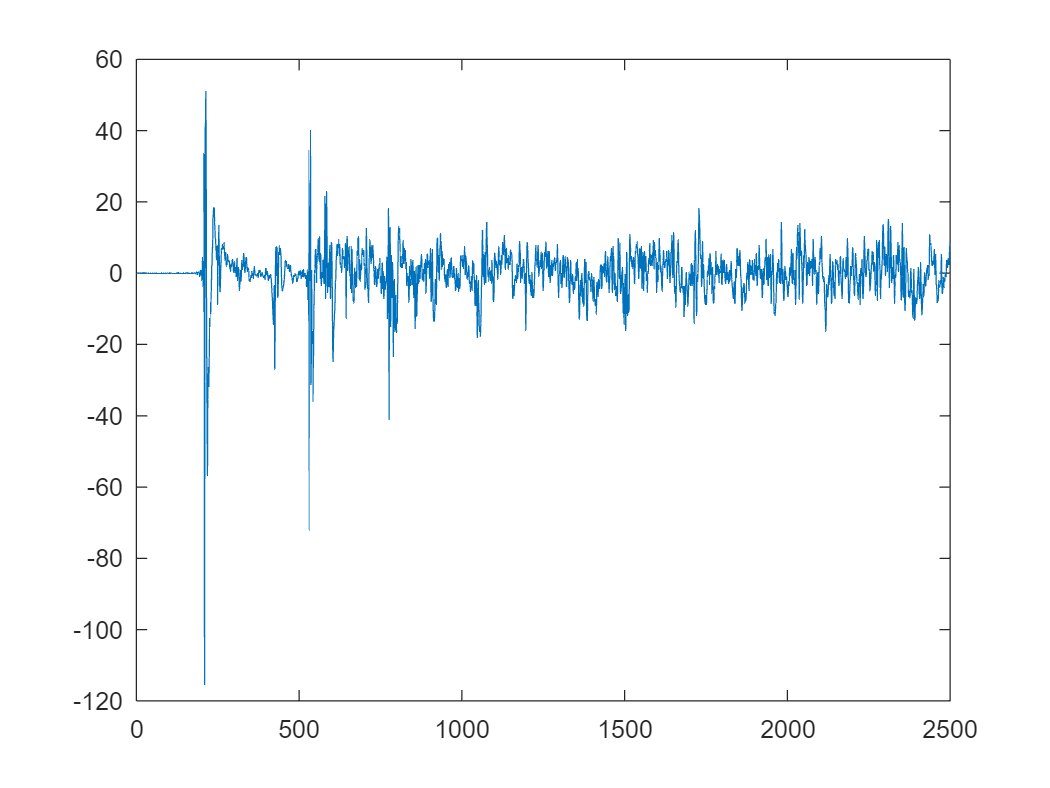

% Test if computing RIR went well

plot(speakers_all_discrete_positions{5,1}(:,1))

a = createSDMStruct('DefaultArray','GRASVI50','fs',fs,'winLen',15);

User-defined SDM Settings are used :
           fs: 48000
            c: 345
       winLen: 15
    parFrames: 8192
    showArray: 0
      micLocs: [6×3 double]



DOA = cell(number_of_discrete_positions,number_of_speakers);
P = cell(number_of_discrete_positions,number_of_speakers);

% Calculate DOA

for i=1:number_of_discrete_positions
    DOA{i,1} = SDMbf(speakers_all_discrete_positions{i,1}, a);
end

Started SDM processing
Ended SDM processing in 0.036146 seconds.
Started SDM processing
Ended SDM processing in 0.0011006 seconds.
Started SDM processing
Ended SDM processing in 0.001442 seconds.
Started SDM processing
Ended SDM processing in 0.0009905 seconds.
Started SDM processing
Ended SDM processing in 0.0066077 seconds.
Started SDM processing
Ended SDM processing in 0.0003954 seconds.
Started SDM processing
Ended SDM processing in 0.0001933 seconds.
Started SDM processing
Ended SDM processing in 0.000167 seconds.
Started SDM processing
Ended SDM processing in 0.0001635 seconds.
Started SDM processing
Ended SDM processing in 0.0001671 seconds.
Started SDM processing
Ended SDM processing in 0.0001559 seconds.
Started SDM processing
Ended SDM processing in 0.0001755 seconds.



for i=1:number_of_discrete_positions
    DOA{i,2} = SDMbf(speakers_all_discrete_positions{i,2}, a);
end

Started SDM processing
Ended SDM processing in 0.0003665 seconds.
Started SDM processing
Ended SDM processing in 0.0003243 seconds.
Started SDM processing
Ended SDM processing in 0.000337 seconds.
Started SDM processing
Ended SDM processing in 0.0002713 seconds.
Started SDM processing
Ended SDM processing in 0.0005533 seconds.
Started SDM processing
Ended SDM processing in 0.0004611 seconds.
Started SDM processing
Ended SDM processing in 0.0002904 seconds.
Started SDM processing
Ended SDM processing in 0.000233 seconds.
Started SDM processing
Ended SDM processing in 0.0002055 seconds.
Started SDM processing
Ended SDM processing in 0.0002337 seconds.
Started SDM processing
Ended SDM processing in 0.0002334 seconds.
Started SDM processing
Ended SDM processing in 0.0002412 seconds.


% TAKE THE MIDDLE ONE OF THE MICROPHONE ARRAY, THIS IS THE TOP ONE,MICROPHONE E

for i=1:number_of_discrete_positions
    P{i,1} = speakers_all_discrete_positions{i,1}(:,5);
end

for i=1:number_of_discrete_positions
    P{i,2} = speakers_all_discrete_positions{i,2}(:,5);
end

%save variables in file to use it in another file
save("opt_truncated_mat_files\pressure.mat","P")
save("opt_truncated_mat_files\DOA.mat","DOA")
save("opt_truncated_mat_files\rir.mat","speakers_all_discrete_positions")